**PART ONE:**

Capturing Reference Image and saving to a DataBase

**Step 1:** Connecting to Webcam

cam = webcam(); 

**Step 2:** Capturing New Image

mainImage = snapshot(cam); 

**Step 3:** Converting to Gray Scale

mainImageGray = rgb2gray(mainImage);

**Step 4:** Detecting the face in the image.

faceDetector = vision.CascadeObjectDetector();
bboxes = step(faceDetector, mainImageGray);

**Step 5:** Focus on the Largest(Main) Face in the shot

if ~isempty(bboxes)
   [~, largestFaceIdx] = max(bboxes(:,3) .* bboxes(:,4)); % Area of bounding box
    mainFaceBox = bboxes(largestFaceIdx, :);
    mainFaceImg = imcrop(mainImageGray, mainFaceBox); 

**Step 6:** Resize the Image

    mainFaceImgResized = imresize(mainFaceImg, [128 128]);

**Step 7:** Extract Unique Features

     mainHOGFeatures = extractHOGFeatures(mainFaceImgResized);

**Step 8:** Save the Extracted Features to a Matlab Files

    save('mainFaceHOGFeatures.mat', 'mainHOGFeatures', 'mainFaceImgResized');

**Step 9:** Display the new face image

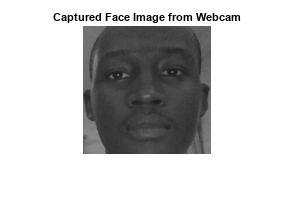

Face detected and features saved.


      figure;
    imshow(mainFaceImgResized);
    title('Captured Face Image from Webcam');
    
    disp('Face detected and features saved.');
else
    disp('No face detected. Please try again.');
end

**Step 10:**Close Webcam

clear cam;